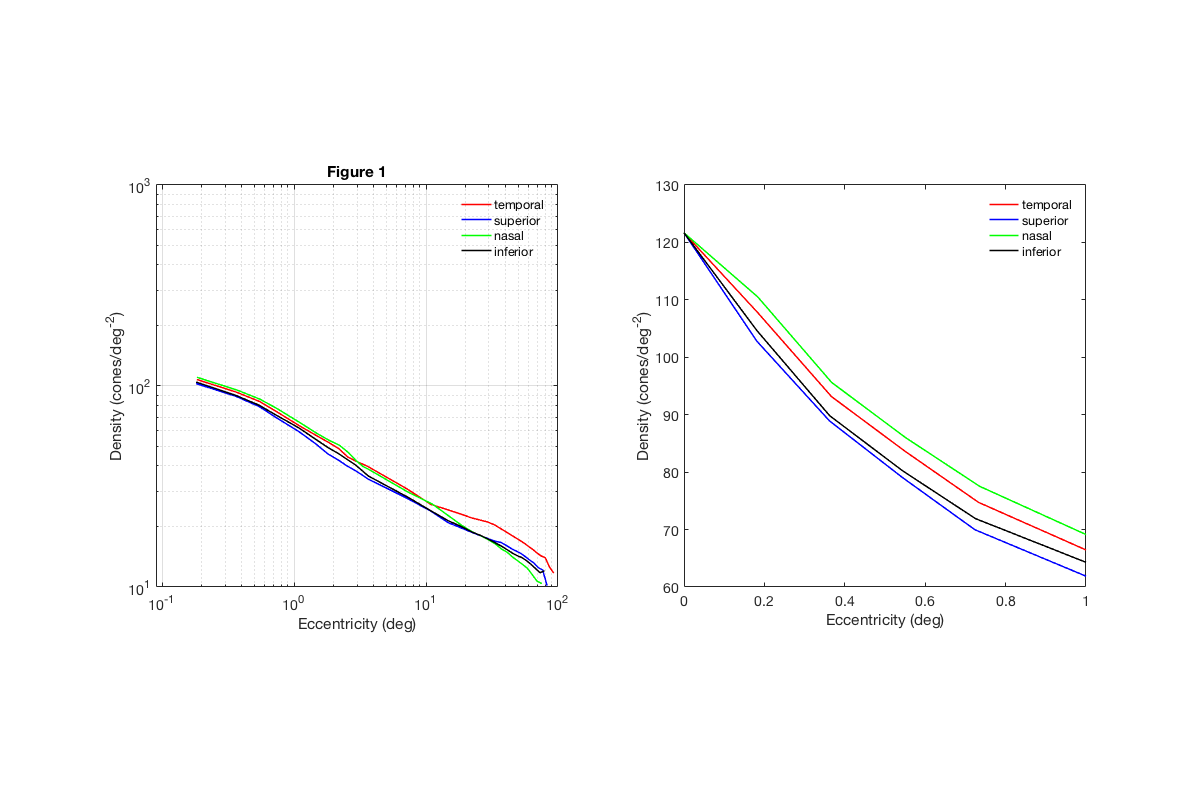

clear all; clc; close all;
%load data
dataLoad_all;
%% plot Curcio Cone Densities in deg (figure 1)
figure;
subplot(1,2,1);loglog(xt_deg_c,yt_deg_c,'r',xs_deg_c,ys_deg_c,'b',xn_deg_c,yn_deg_c,...
'g',xi_deg_c,yi_deg_c,'k','linewidth',1.5);
xlim([0.09 100]); xlabel('Eccentricity (deg)'); ylabel('Density (cones/deg^-^2)');
legend('temporal','superior','nasal','inferior'); legend('boxoff');axis square
title('Figure 1'); grid on;
%plot only first degree
subplot(1,2,2);plot(xt_deg_c(1:6),yt_deg_c(1:6),'r',xs_deg_c(1:6),ys_deg_c(1:6)...
,'b',xn_deg_c(1:6),yn_deg_c(1:6),'g',xi_deg_c(1:6),yi_deg_c(1:6),'k','linewidth',1.5);
xlim([0 1]); xlabel('Eccentricity (deg)'); ylabel('Density (cones/deg^-^2)');
legend('temporal','superior','nasal','inferior'); legend('boxoff');axis square

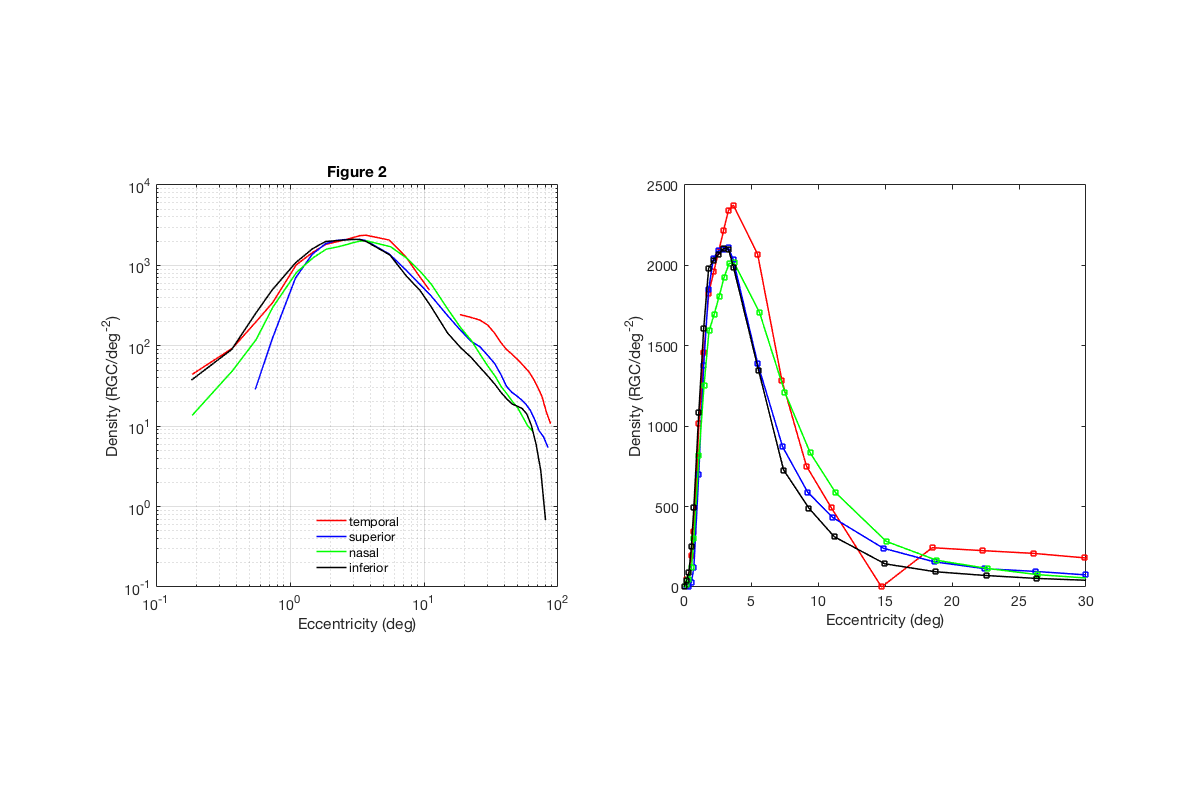


%% Plot Curcio Retinal Ganglion Cell Densities (figure 2)
figure;
subplot(1,2,1);loglog(xt_deg_rgcd,yt_deg_rgcd,'r',xs_deg_rgcd,ys_deg_rgcd,'b',xn_deg_rgcd,yn_deg_rgcd,...
'g',xi_deg_rgcd,yi_deg_rgcd,'k','linewidth',1.5);
xlim([0.1 100]); xlabel('Eccentricity (deg)'); ylabel('Density (RGC/deg^-^2)');
legend('temporal','superior','nasal','inferior'); legend('boxoff');
legend('location','south');axis square;title('Figure 2'); grid on;
%plot only first twenty degree
subplot(1,2,2);plot(xt_deg_rgcd(1:30),yt_deg_rgcd(1:30),'-sr',xs_deg_rgcd(1:30),ys_deg_rgcd(1:30),...
'-sb',xn_deg_rgcd(1:30),yn_deg_rgcd(1:30),'-sg',xi_deg_rgcd(1:30),yi_deg_rgcd(1:30),'-sk','linewidth',1.5);
xlim([0 30]); xlabel('Eccentricity (deg)'); ylabel('Density (RGC/deg^-^2)'); axis square; hold on

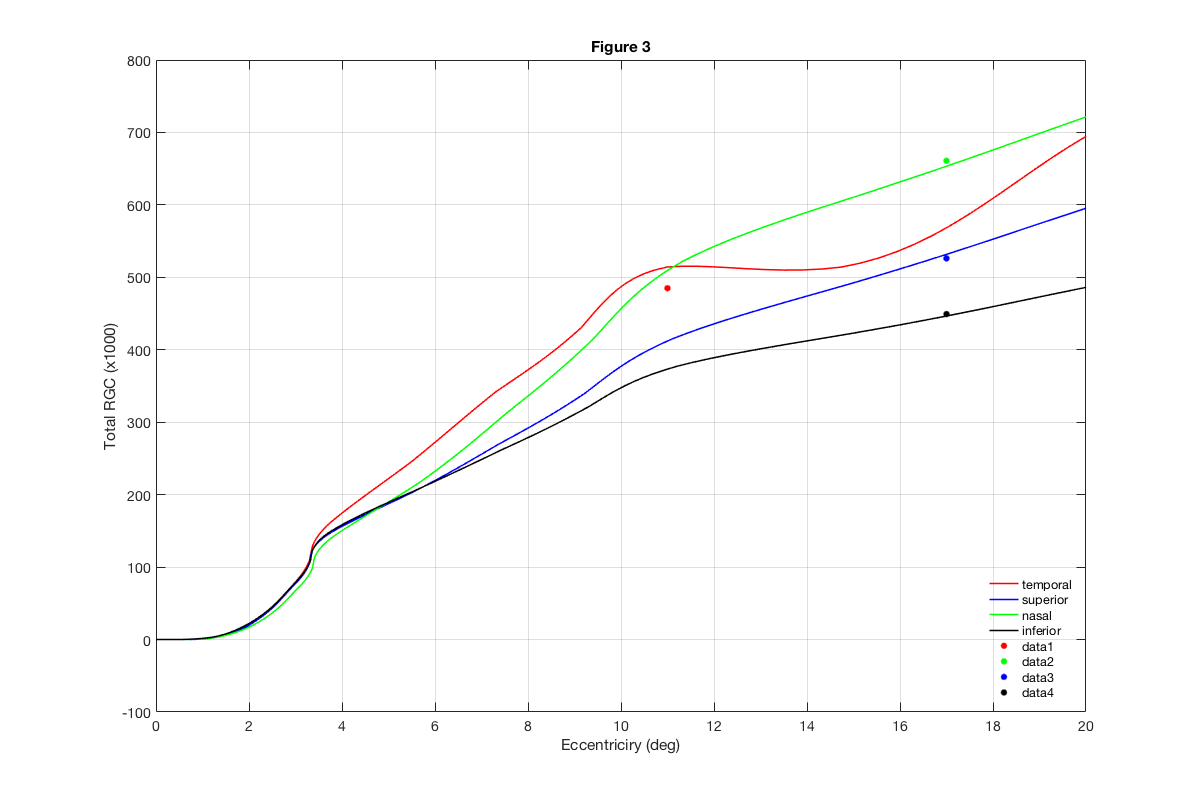


%% plot Total RGC count (figure 3)
rgc_count;
%interpolate x-axis for diff x-vals
for xx = 1:length(eccIdx)
    xdata = eval(x_nameIdx{xx});
    xinterp = xdata(1:eccIdx(xx));
    x_vals(:,xx) = interp(xinterp,10);
    clear xinterp
end
%plot all interpolated data
figure;
plot(x_vals(:,3),locInt(:,3),'r',x_vals(:,4),locInt(:,4),'b',x_vals(:,2),locInt(:,2),...
'g',x_vals(:,1),locInt(:,1),'k','linewidth',1.5); grid on;
legend('temporal','superior','nasal','inferior'); legend('boxoff'); legend('location','southeast')
xlim([0 20]); ylabel('Total RGC (x1000)'); xlabel('Eccentriciry (deg)'); hold on;
title('Figure 3')
%plot displacement zone
%data points taken from table in paper
%not sure why the lines arent an exact match - specially for the temporal retina
h1 = plot(11,485.1,'.r','markersize',20); h2 = plot(17,660.9,'.g','markersize',20); 
h3 = plot(17,526.1,'.b','markersize',20); h4 = plot(17,449.3,'.k','markersize',20);

%remove legend markers for displacement zone
set(get(get(h1,'Annotation'),'LegendInformation'),'IconDisplayStyle','off');
set(get(get(h2,'Annotation'),'LegendInformation'),'IconDisplayStyle','off');
set(get(get(h3,'Annotation'),'LegendInformation'),'IconDisplayStyle','off');
set(get(get(h4,'Annotation'),'LegendInformation'),'IconDisplayStyle','off');
% Not sure why the displacement zone doesn't match for temporal retina
% I followed the math in the paper...
%% fit area outside displacement zone (figure 4)
titleNames = {'temporal','Superior','Nasal','Inferior'}; 
x_nameIdx = {'xt_deg_rgcd','xs_deg_rgcd','xn_deg_rgcd','xi_deg_rgcd'}; 
y_nameIdx = {'yt_deg_rgcd','ys_deg_rgcd','yn_deg_rgcd','yi_deg_rgcd'}; 
opt = optimoptions('fmincon','Algorithm','interior-point','MaxIter',10000);
% initial values for optmization
% taken from paper (table 1) ... fmincon was not arriving at best vals on
% its own. Thought Id help it out...turns out it doesnt really...somethings
% weird when I fit all the eccentricities. 
% x0_init = [0.9851,1.058,22.14;...
%            0.9935,1.035,16.35;...
%            0.9729,1.084,7.633;...
%            0.9960,0.9932,12.13];
for ii = 1:length(x_nameIdx)
    if ii ==1 
        dispZoneIdx =12; %17
    else
        dispZoneIdx =19; %19
    end
    y = eval(y_nameIdx{ii}); y = y(dispZoneIdx:end)'; 
    ecc = eval(x_nameIdx{ii}); ecc = ecc(dispZoneIdx:end)';
    %free paramaters
    %1-first term weight
    %2-ecc at which density is reduced by factor of four
    %3-scale factor of exponential
    %bounds where chosen to be in proximity to actual values used in the paper (table 1)
	ub = [1, 2, 25];  %upper bound
	lb = [-1, 1, 7];  %lower bound
    %ub = x0_init(ii,:); lb = x0_init(ii,:);
    %x0 = x0_init(ii,:); %starting values - chosen as best fits from paper (table 1)
    x0 = [0.97,1.035,15];
    f = @(x)fit_displacementZone(x,y,ecc);
    [x,fval,exitflag,output,grad,hessian] = fmincon(f,x0,[],[],[],[],lb,ub,[],opt);
    %center,gain,sigma,p,base
    [~,temp] = fit_displacementZone(x,y,ecc);
    %store vars 
    fittedVals{ii} = temp;
    ogecc{ii} = ecc;
    ogy{ii}=y;
    params(:,ii) = x;
    clear temp ecc y 
    %interpolate to match xvals
    %interpFit{ii} = interp(temp,3);
end


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the default value of the step size tolerance and constraints are 
satisfied to within the default value of the constraint tolerance.




Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the default value of the step size tolerance and constraints are 
satisfied to within the default value of the constraint tolerance.




Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the default value of the step size tolerance and constraints are 
satisfied to within the default value of the constraint tolerance.




Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the default value of the step size tolerance and constraints are 
satisfied to within the default value of the constraint tolerance.

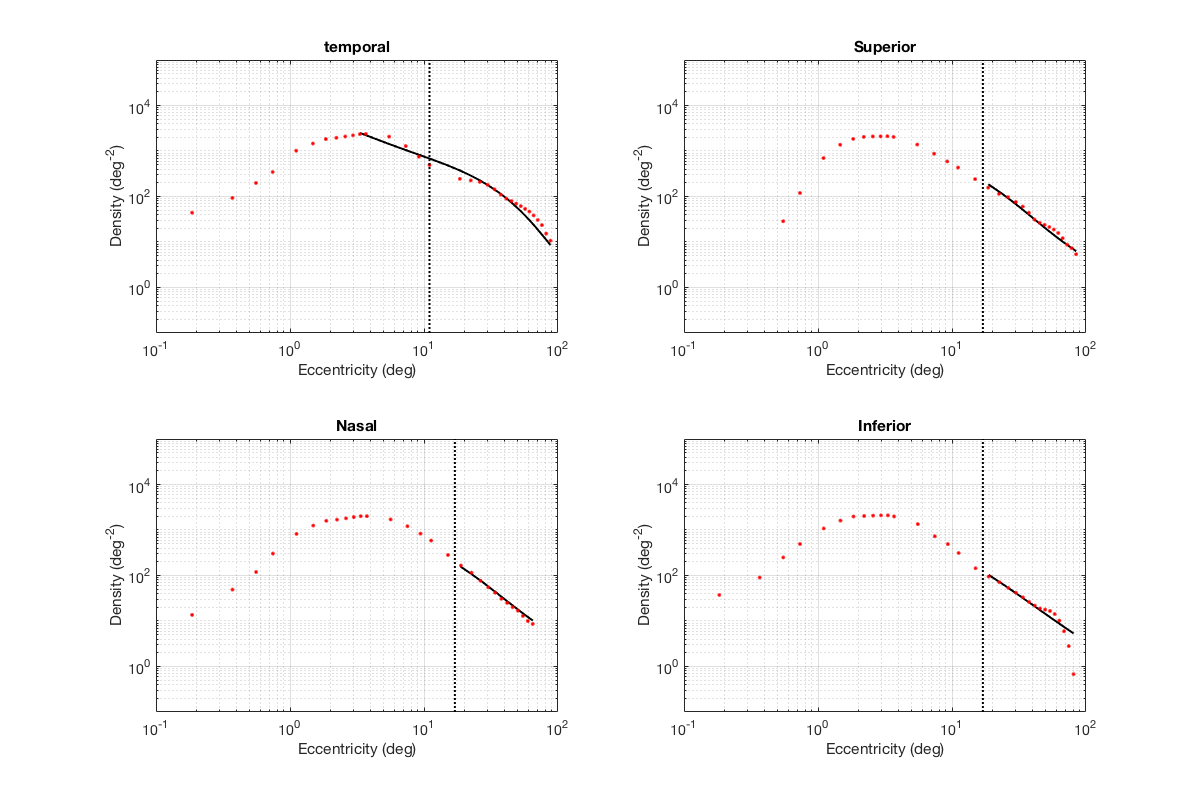


% plot data points (figure 4)
figure;
for ii = 1:length(x_nameIdx)
    subplot(2,2,ii);loglog(ogecc{ii},fittedVals{ii},'-k','linewidth',2); hold on; grid on
    subplot(2,2,ii);loglog(eval(x_nameIdx{ii}),eval(y_nameIdx{ii}),'.r','markersize',10); 
    xlim([0.1 100]); ylim([0.1 10^5])
    if ii == 1
        line([11, 11],ylim,'linestyle',':','color','k','linewidth',2);
    else
        line([17, 17],ylim,'linestyle',':','color','k','linewidth',2);
    end
    xlabel('Eccentricity (deg)'); ylabel('Density (deg^-^2)');
    title(titleNames{ii}); 
end

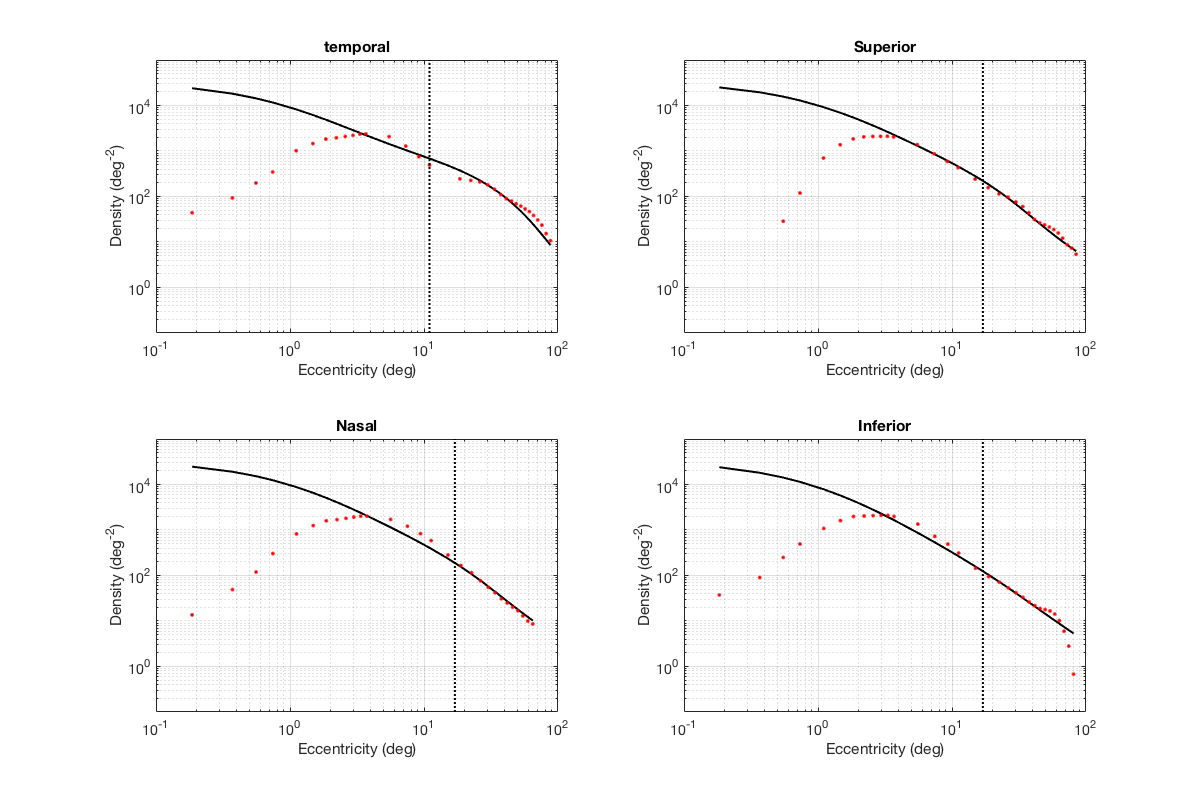


%% Use fitted params to plot entire curve
for ii = 1:length(x_nameIdx)
    y = eval(y_nameIdx{ii}); y = y(1:end)'; 
    ecc = eval(x_nameIdx{ii}); ecc = ecc(1:end)';
    [~,fit{ii}] = fit_displacementZone(params(:,ii),y,ecc);
    ogecc{ii} = ecc;
end
%plot
figure;
for ii = 1:length(x_nameIdx)
    subplot(2,2,ii);loglog(ogecc{ii},fit{ii},'-k','linewidth',2); hold on; grid on
    subplot(2,2,ii);loglog(eval(x_nameIdx{ii}),eval(y_nameIdx{ii}),'.r','markersize',10); 
    xlim([0.1 100]); ylim([0.1 10^5])
    if ii == 1
        line([11, 11],ylim,'linestyle',':','color','k','linewidth',2);
    else
        line([17, 17],ylim,'linestyle',':','color','k','linewidth',2);
    end
    xlabel('Eccentricity (deg)'); ylabel('Density (deg^-^2)');
    title(titleNames{ii}); 
end

paper_p = [0.9851,1.058,22.14;...
           0.9935,1.035,16.35;...
           0.9729,1.084,7.633;...
           0.9960,0.9932,12.13];
%seems like fmincon does a better job of fitting the points ... there are
%some big differences in the last parameter
disp('Here are the fmincon params:'); 

Here are the fmincon params:


disp('Each column is a retinal location (from left: temporal/superior/nasal/inferior)'); disp(' ');

Each column is a retinal location (from left: temporal/superior/nasal/inferior)
 


disp(num2str(params)); disp(' ');

0.973617     0.984413     0.988507     0.997436
 1.02248      1.18199      1.15004      1.03713
 16.5155      9.32497      8.98717      9.74558
 


disp('Here are the paper params:'); disp(' ');

Here are the paper params:
 


disp(num2str(paper_p')); disp(' ');

0.9851       0.9935       0.9729        0.996
 1.058        1.035        1.084       0.9932
 22.14        16.35        7.633        12.13
 


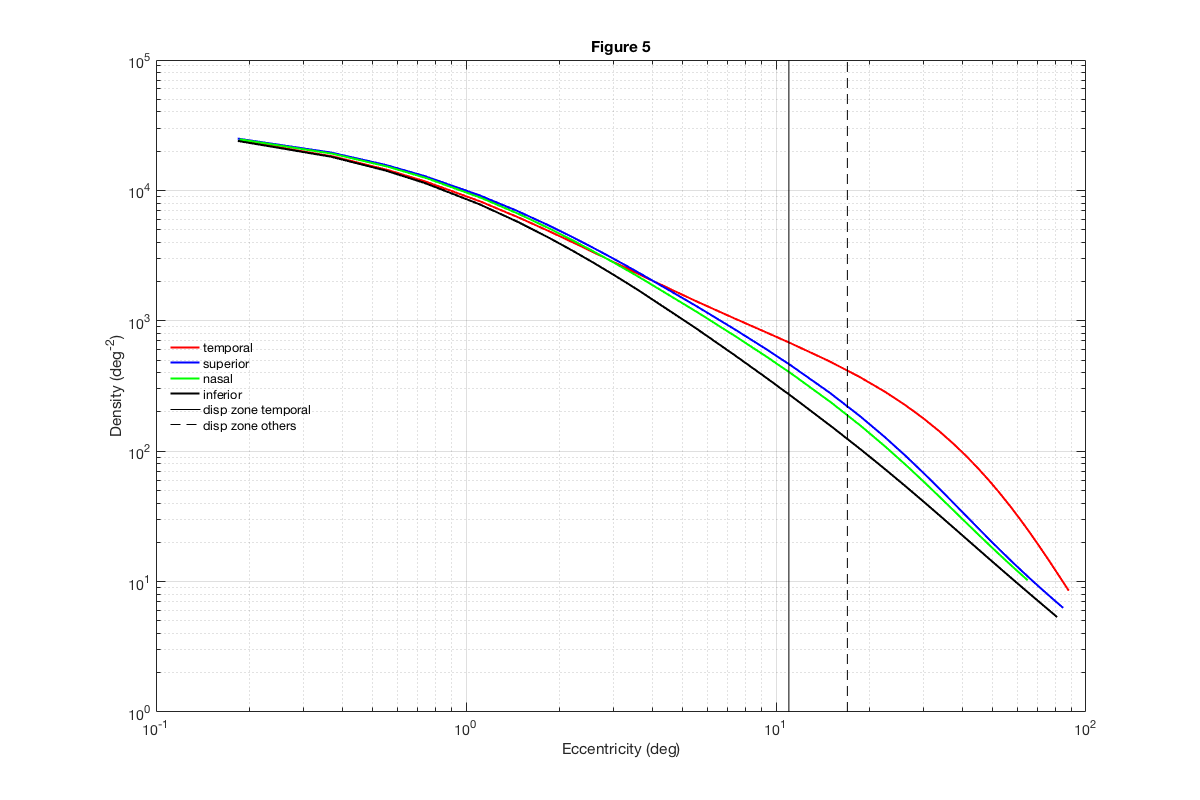

%% replot the fits in their own plot (figure 5)
figure;
loglog(ogecc{1},fit{1},'r',ogecc{2},fit{2},'b',...
    ogecc{3},fit{3},'g',ogecc{4},fit{4},'k','linewidth',2);
%xlim([8 100]);
line([11 11],ylim,'color','k','linestyle','-');
line([17 17],ylim,'color','k','linestyle','--');
legend('temporal','superior','nasal','inferior',...
    'disp zone temporal','disp zone others'); 
legend('boxoff'); legend('location','northeast');
title('Figure 5'); grid on
legend('location','west');
ylabel('Density (deg^-^2)');
xlabel('Eccentricity (deg)');

%% Modeled displacement functions (solid curve) and points from the formula of Drasdo et al. (2007) (Figure 6)
%load drasdo et al, data...approximation don't have actual data...
%its inside dataLoad_all
%set dara
nasal = drasdo_data_l(5:44,:);
temporal = drasdo_data_l(45:end-5,:);
%fit new function to nasal and temporal retina 
opt = optimoptions('fmincon','Algorithm','interior-point','MaxIter',10000);
for ii = 1:2
    if ii == 1
        ecc = temporal(:,1); y = temporal(:,2);
        type = 1;
    else
        %needs positive x vals
        ecc = abs(nasal(:,1)); y = nasal(:,2);
        type = 2;
    end
%     y = eval(y_nameIdx{ii}); y = y(1:N)'; 
%     ecc = eval(x_nameIdx{ii}); ecc = ecc(1:N)';
    %bounds where chosen to be in proximity to actual values used in the paper (table 1)
	ub = [1.1,0,2.5,15.5,2.5];  %upper bound (gamma,mu,beta,delta,alpha)
	lb = [0.5,-0.1,1.7,14,2];  %lower bound
    x0 = [1.1,-0.1,2.45,15,2]; %starting point
    f = @(x)fit_displacementZoneNasalTemporal(x,y,ecc,type,1);
    [x] = fmincon(f,x0,[],[],[],[],lb,ub,[],opt);
    %
    [~,temp] = fit_displacementZoneNasalTemporal(x,y,ecc,type,1);
    %store vars 
    fittedVals_n{ii} = temp;
    ogecc_n{ii} = ecc;
    ogy_n{ii}=y;
    params_n(:,ii) = x;
    clear temp ecc y 
end


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the default value of the optimality tolerance,
and constraints are satisfied to within the default value of the constraint tolerance.




Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the default value of the optimality tolerance,
and constraints are satisfied to within the default value of the constraint tolerance.





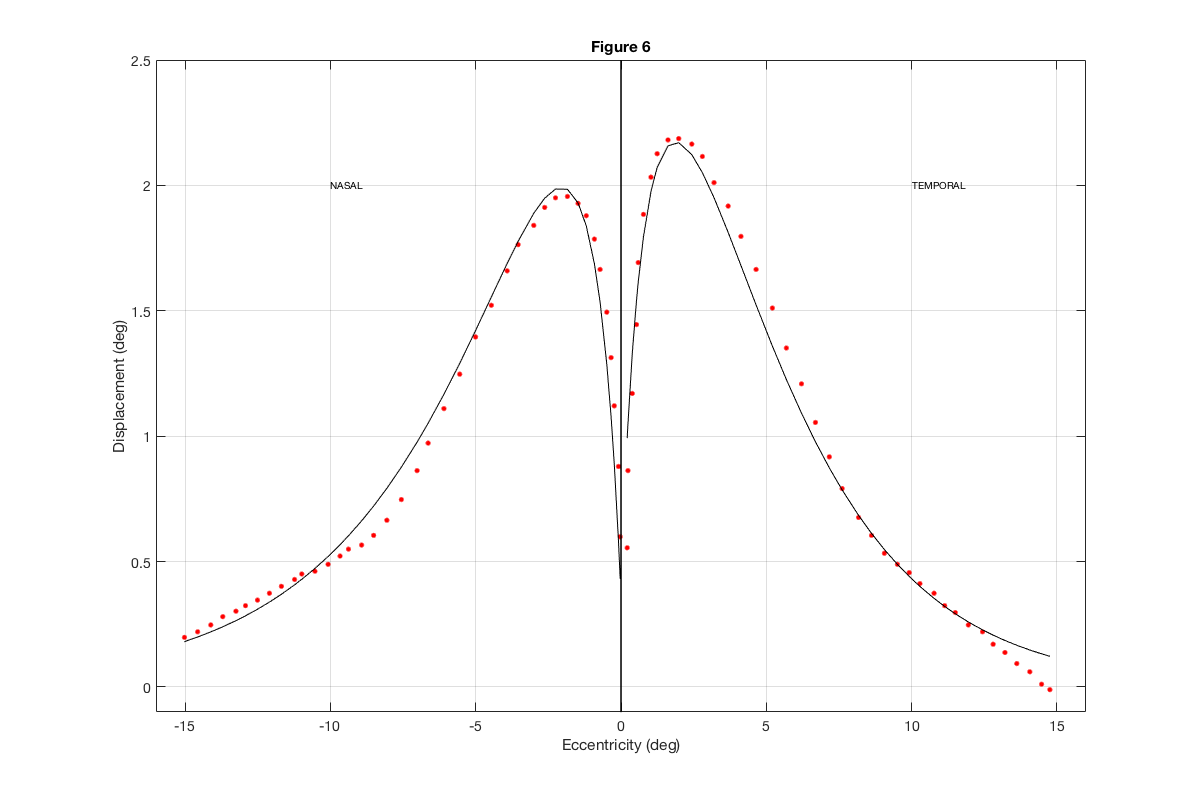

figure; 
plot(temporal(:,1),temporal(:,2),'r.',...
    nasal(:,1),nasal(:,2),'r.','markersize',15); hold on;
line([0,0],ylim,'color','k','linewidth',1.5); grid on; title('Figure 6');
%
plot(temporal(:,1),fittedVals_n{1},'k',...
    nasal(:,1),fittedVals_n{2},'k','markersize',15); hold on;
ylim([-0.1, 2.5]); xlim([-16,16]);
%add text
text(10,2,'TEMPORAL');
text(-10,2,'NASAL');
ylabel('Displacement (deg)');
xlabel('Eccentricity (deg)')

%% Modeled displacement function based of Watson formula (figure 7)
opt = optimoptions('fmincon','Algorithm','interior-point','MaxIter',10000);
nasal = watson_form(1:16,:);
temporal = watson_form(18:end,:);
for ii = 1:2
    if ii == 1
        ecc = temporal(:,1); y = temporal(:,2);
    else
        %needs positive x vals
        ecc = abs(nasal(:,1)); y = nasal(:,2);
    end
    
    ub = [1.3,0,50,inf,2.5];  %upper bound (gamma,mu,beta,delta,alpha)
	lb = [1,-0.1,3.5,-inf,2];  %lower bound
    x0 = [1.1,0,10,700,2]; %starting point
    f = @(x)fit_displacementZoneNasalTemporal(x,y,ecc,[],2);
    [x] = fmincon(f,x0,[],[],[],[],lb,ub,[],opt);
    %
    [~,temp] = fit_displacementZoneNasalTemporal(x,y,ecc,[],2);
    %store vars 
    fittedVals_nn{ii} = temp;
    ogecc_nn{ii} = ecc;
    ogy_nn{ii}=y;
    params_nn(:,ii) = x;
    clear temp ecc y 
end


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the default value of the step size tolerance and constraints are 
satisfied to within the default value of the constraint tolerance.




Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the default value of the step size tolerance and constraints are 
satisfied to within the default value of the constraint tolerance.





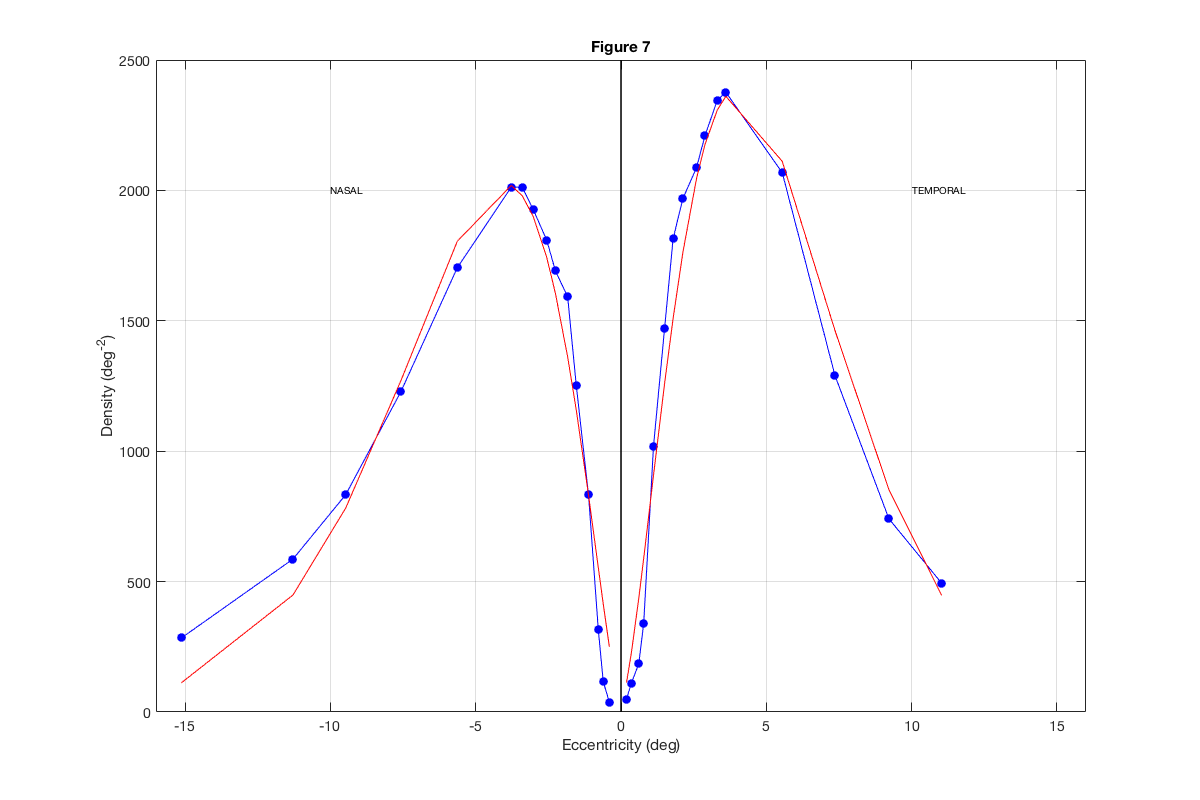

% not really sure why in the paper Watson says that the points generated by
% his formula arent fit well by the new displacement function (figure
% 6)...If anything I found that they fit even better. Perhaps he plotted
% temporal and nasal fits on the wrong side in the plot ... I dont know.
figure; 
plot(temporal(:,1),temporal(:,2),'-b.',...
    nasal(:,1),nasal(:,2),'-b.','markersize',30); hold on;
line([0,0],ylim,'color','k','linewidth',1.5); grid on; title('Figure 7');
%
plot(temporal(:,1),fittedVals_nn{1},'r',...
    nasal(:,1),fittedVals_nn{2},'r','markersize',15); hold on;
%ylim([-0.1, 2.5]); 
xlim([-16,16]);
ylabel('Density (deg^-^2)');
xlabel('Eccentricity (deg)')
%add text
text(10,2000,'TEMPORAL');
text(-10,2000,'NASAL');

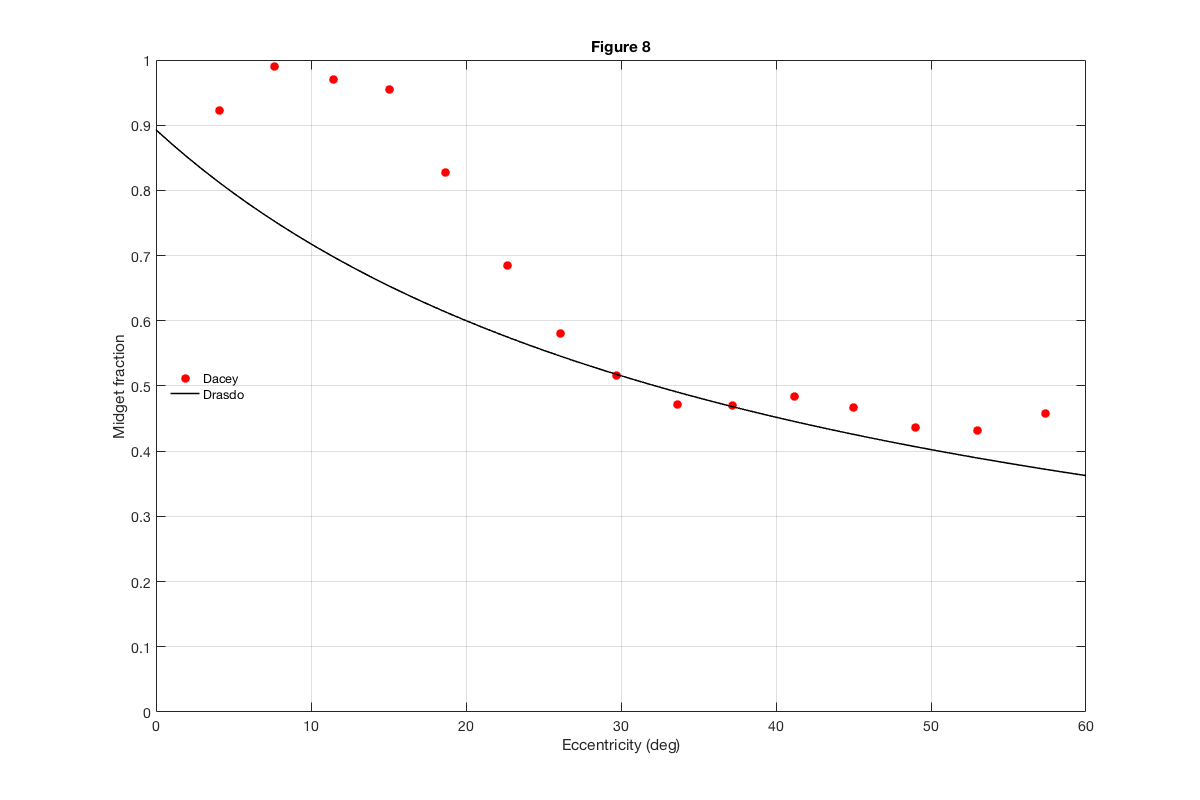

%% Estimated fraction of RGC that are midget cells as a function of eccentricity (Figure 8)
fzero = 1/1.12;
rm = 41.03;
r = 0:60;
% drasdo formula for mRGC (Drasdo et al., 2007)
drasdoform = fzero*(1+(r/rm)).^-1;
%plot Dacey and Drasdo data
figure;
plot(DaceyData(:,1),DaceyData(:,2),'r.','markersize',30); hold on
plot(r,drasdoform,'k-','linewidth',1.5); grid on;
xlim([0 60]); ylim([0 1]); 
ylabel('Midget fraction'); 
xlabel('Eccentricity (deg)');
legend('Dacey','Drasdo'); 
legend('boxoff'); 
legend('location','west');
title('Figure 8')

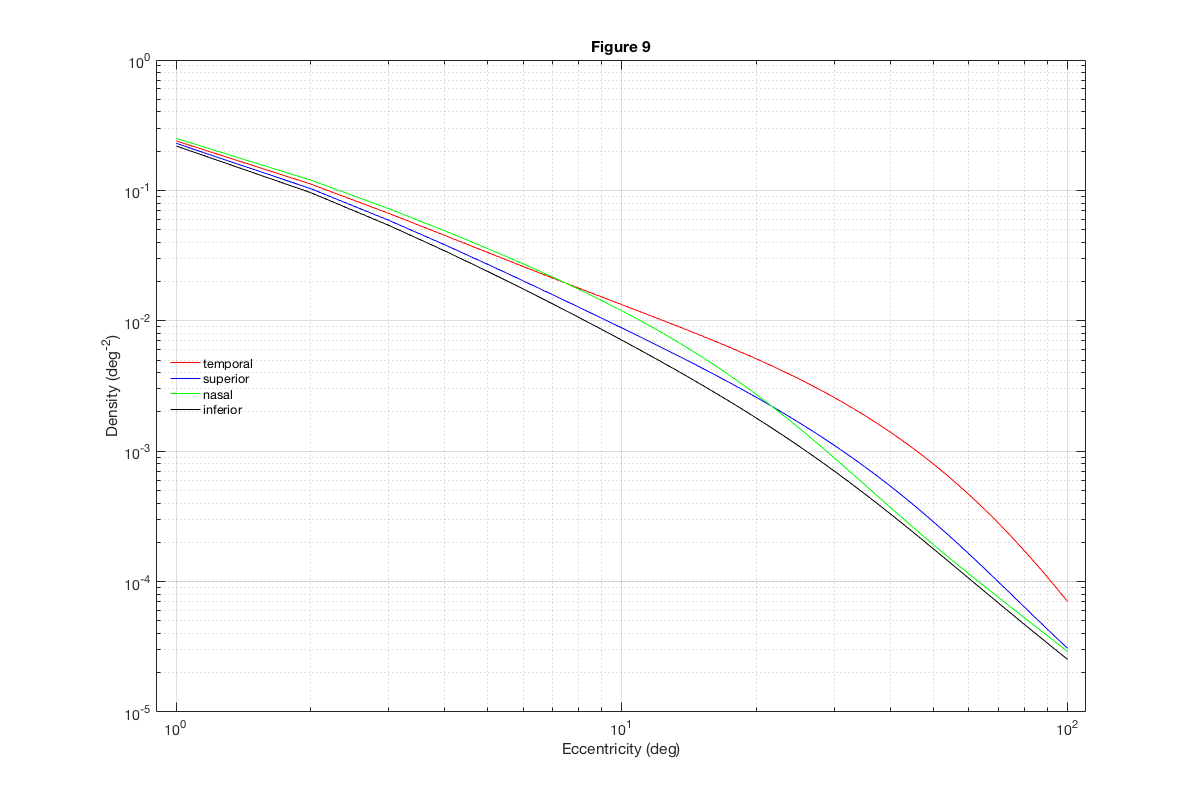

%% mRGCf density formula as a function of eccentricity (Figure 9 - combining Drasdo & Watson formula)
fzero = 1/1.12;
rm = 41.03;
r_ = 0:100;
for ii = 1:length(paper_p)
    %temporal/superior/nasal/inferior
    a = paper_p(ii,1);
    r2 = paper_p(ii,2);
    re = paper_p(ii,3);
    % drasdo formula for mRGC (Drasdo et al., 2007)
    drasdo = 1/1.12*(1+(r_/41.03)).^-1;
    % now for watson formula
    watsonDrasdo(ii,:) = drasdo.*(a*(1+r_./r2).^-2+(1-a)*exp(-r_/re));
end
figure;
loglog(r_,watsonDrasdo(1,:),'r',r_,watsonDrasdo(2,:),'b',...
    r_,watsonDrasdo(3,:),'g',r_,watsonDrasdo(4,:),'k'); grid on
legend('temporal','superior','nasal','inferior');
legend('boxoff'); legend('location','northeast');
title('Figure 9'); xlim([0.9 110]);
legend('location','west');
xlabel('Eccentricity (deg)'); ylabel('Density (deg^-^2)');

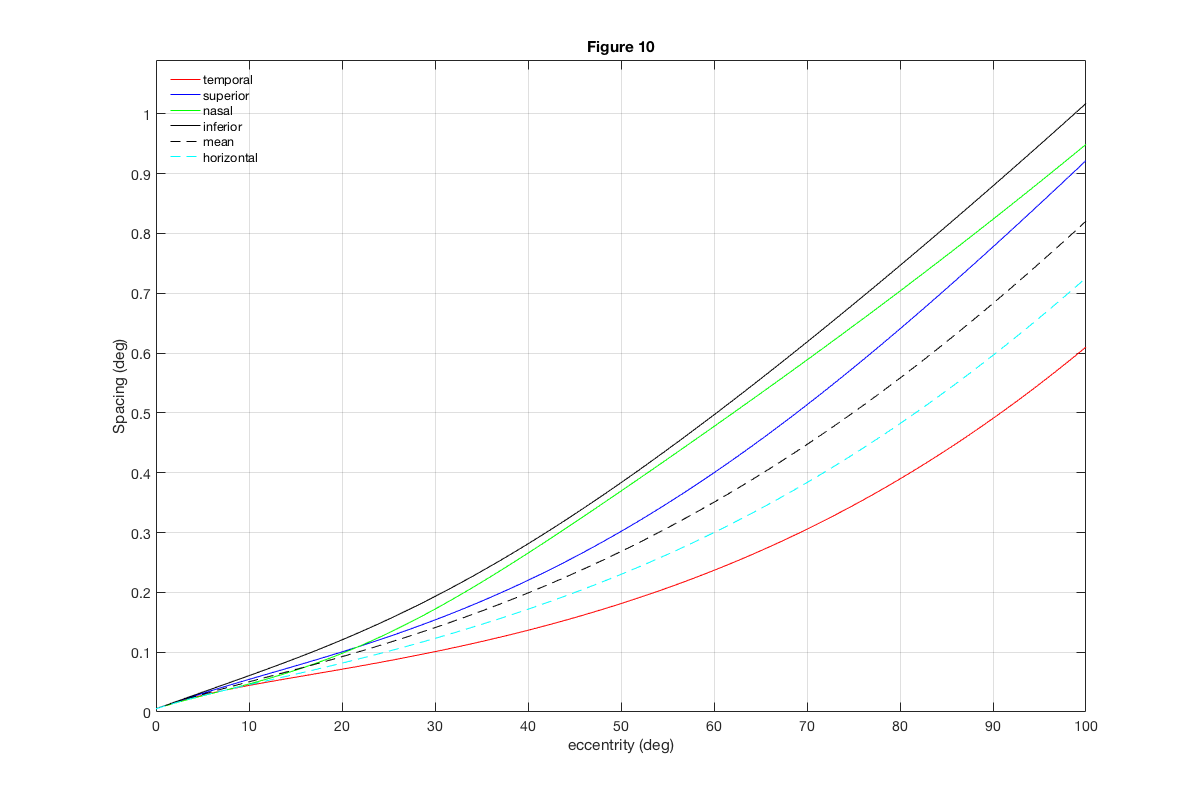

%% Formula for mRGCf spacing (Figure 10)
% using the arbitrary x-values from figure 9
for ii = 1:size(watsonDrasdo,1)
    smf{ii} = sqrt(2./(sqrt(3)*(watsonDrasdo(ii,:))))./210;
end
%mean & Horizontal spacing calculation
meanSpacing = sqrt(2./(sqrt(3)*(mean(watsonDrasdo))))./210;
Horizontal = sqrt(2./(sqrt(3)*(mean(watsonDrasdo([1,3],:)))))./210;
% plot
figure;
plot(r_,smf{1},'r',r_,smf{2},'b',r_,smf{3},'g',r_,smf{4},'k'); hold on; grid on
plot(r_,meanSpacing,'k--',r_,Horizontal,'c--');
legend('temporal','superior','nasal','inferior','mean','horizontal');
ylim([0 1.09]); xlabel('eccentrity (deg)'); ylabel('Spacing (deg)');
legend('boxoff'); legend('location','northwest');
title('Figure 10');

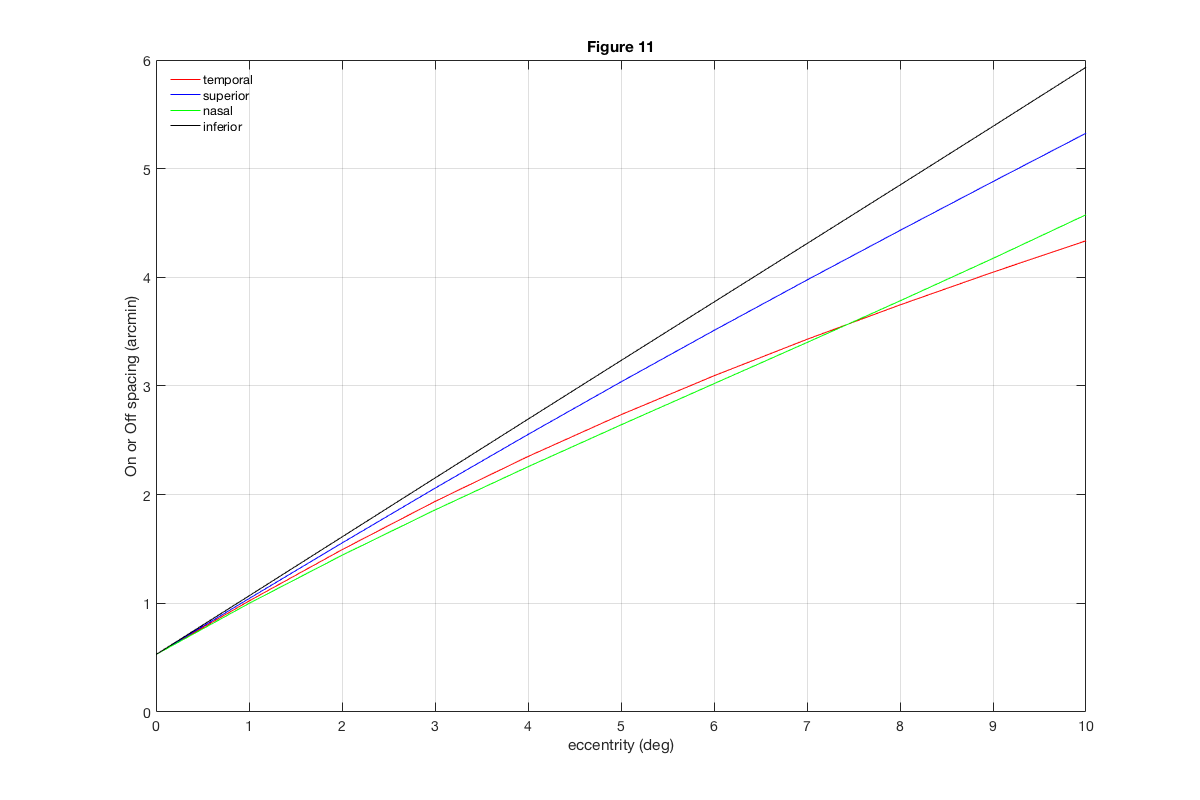

%% Formula for on or off mRGCf spacing for eccentricities 0-10deg (Figure 11)
%Density is halved and the spacings should be multiplied by sqrt of 2
watsonDrasdo = watsonDrasdo/2;
for ii = 1:size(watsonDrasdo,1)
    smf{ii} = sqrt(2./(sqrt(3)*(watsonDrasdo(ii,:))))./4.3;
    smf{ii} = smf{ii}.*sqrt(2);
end
% plot
figure;
plot(r_,smf{1},'r',r_,smf{2},'b',r_,smf{3},'g',r_,smf{4},'k'); hold on; grid on
legend('temporal','superior','nasal','inferior','mean','horizontal');
xlim([0 10]);xlabel('eccentrity (deg)'); ylabel('On or Off spacing (arcmin)');
legend('boxoff'); legend('location','northwest');
title('Figure 11');

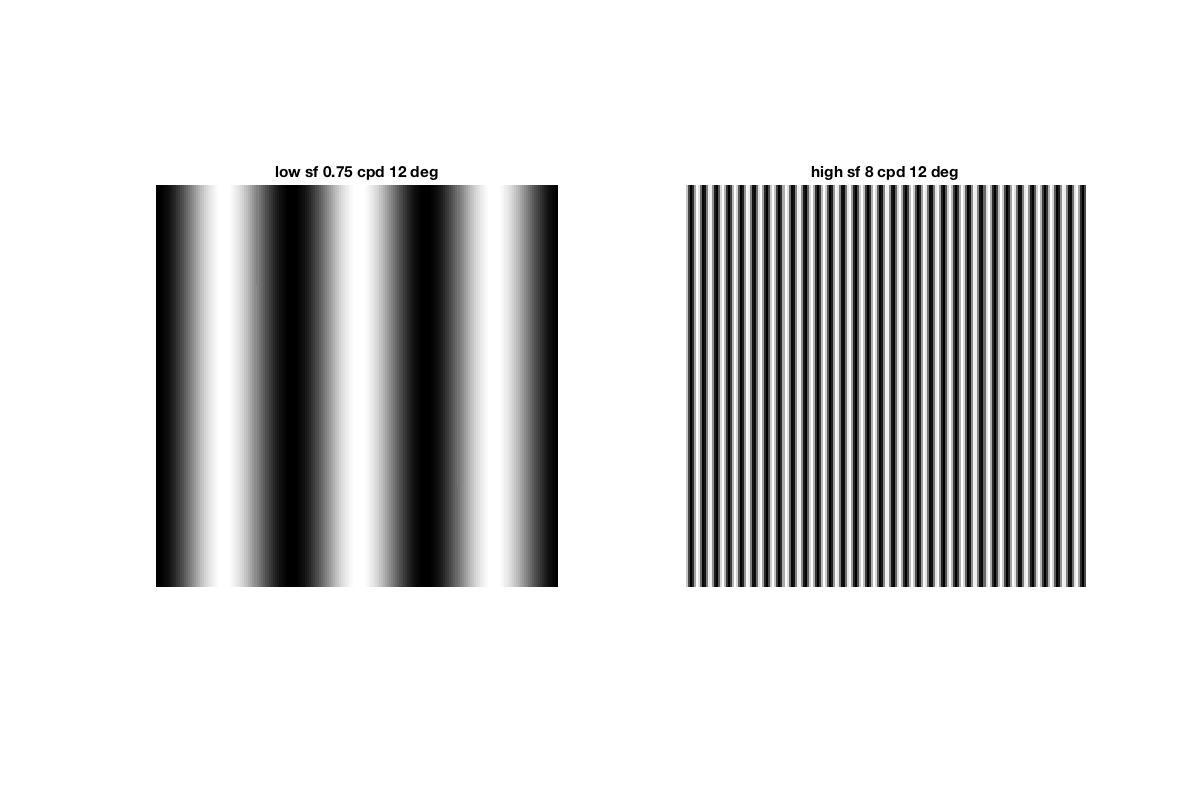

%% Extension to arbitrary retinal location (x,y)
% The idea is to now extend the Watson data so that I can blur an image a
% pixel at a time by calculating the spacing at said pixel!
% The logic is the following: taken from watson paper:
%   " To this point we have developed formulas describing spacing as a 
%   function of eccentricity along each of the four principal meridians. 
%   We would like to extend these formulas to describe spacing at an 
%   arbitrary point {x, y} in the retina. To do this we make the assumption
%   that within any one quadrant of the retina the iso- spacing contours are 
%   ellipses. This is consistent with the idea that spacing changes smoothly 
%   with the angle of a ray extending from the visual center. The 
%   eccentricities at the intersec- tions of the ellipse with the two 
%   enclosing meridians are rx and ry"
%% create gratings
% Now we are going to try and blur two gratings...one of high sf and the
% other low ...
% make vertical grating of sf of 8 & 1 and 11 degs right and left of center
%remove the last row/column to make it symmetrical
figure;
[s,high_freq] = mk_grating(8,90,5); high_freq = high_freq(1:200,1:200);
[~,low_freq] = mk_grating(0.75,90,5); low_freq = low_freq(1:200,1:200);
%plot gratings
subplot(1,2,1);imagesc(low_freq); colormap('gray');
title('low sf 0.75 cpd 12 deg','fontsize',12); axis square; axis off;
subplot(1,2,2);imagesc(high_freq); colormap('gray');
title('high sf 8 cpd 12 deg','fontsize',12); axis square; axis off;

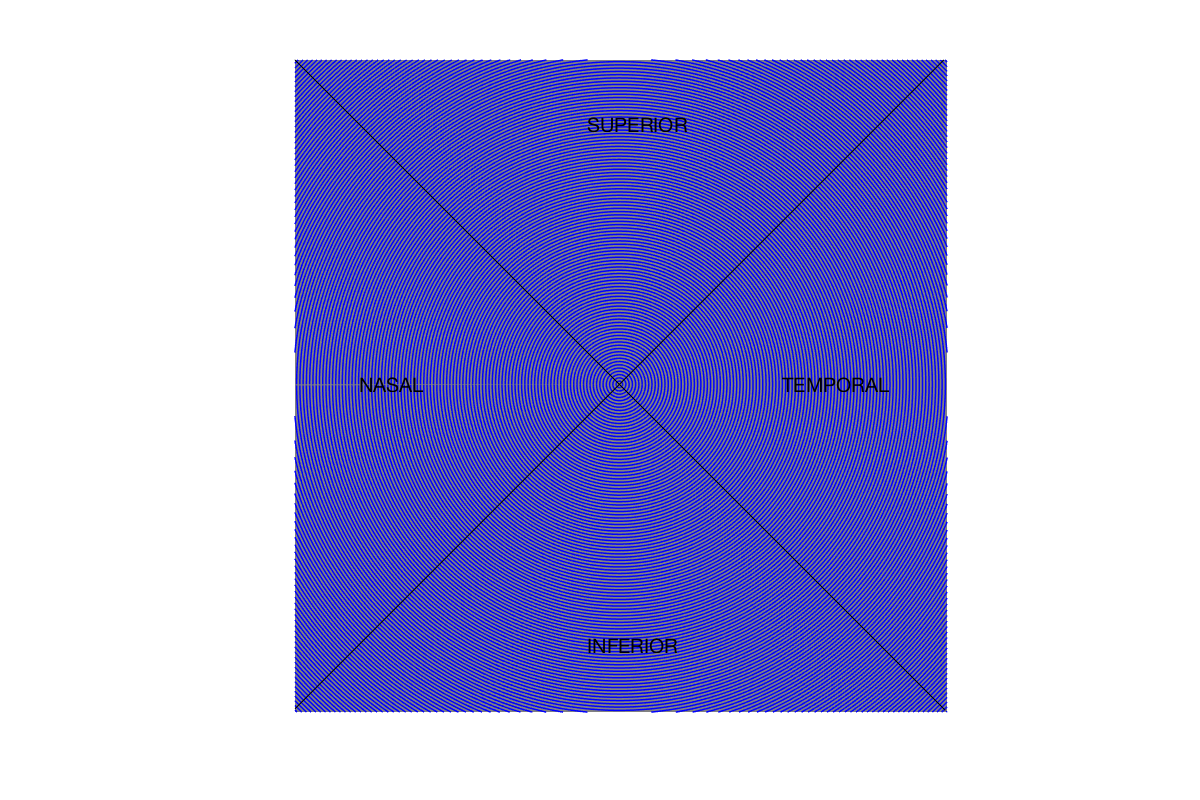

%% separate into all retinal location 
% this is what I will assume as the x-y placement of the retinal locations
% create masks
rows = 200;columns = 200;
xCoords =  [0 100 200; 0 100 200; 0 100 0;200 100 200];
yCoords =  [0 100 0; 200 100 200; 0 100 200; 0 100 200];
for ii = 1:length(xCoords)
mask{ii} = poly2mask(xCoords(ii,:), yCoords(ii,:), rows, columns);
end
full_mask = mask{1}+mask{2}+mask{3}+mask{4};
%% create the iso-spacing contours (from Watson, 14 - equation 11)
%using circles not ellipses...might be a problem dunno
figure; colormap('gray'); 
imagesc(full_mask); axis square; axis off; hold on;
% define spacing in deg 
rx = s(1:200); ry = rx;
midpoint = 100;
% ellipse
for ii = 1:length(rx)
    [x_e{ii},y_e{ii}] = mk_ellipse(rx(1),ry(1),midpoint,midpoint);
    rx = rx+1; ry = ry+1;
    plot(x_e{ii},y_e{ii},'b','linewidth',1.5); 
end
line([0 200], [200 0],'color','k'); 
line([0 200], [0 200],'color','k');
text(90,20,'SUPERIOR','fontsize',20);
text(90,180,'INFERIOR','fontsize',20);
text(150,100,'TEMPORAL','fontsize',20);
text(20,100,'NASAL','fontsize',20);

## Next I have to find which pixels touch which circles to get an rxy coordinate which is gathered through: rxy = sqrt(x^2+y^2)

## **Once that is done I can calculate spacing...which would be used in the future...spacing is given by the following:**

## **s({x,y})  = (1/rxy)*sqrt(x^2*s(rxy,1)^2+y^2*s(rxy,2)^2)**

## **The idea being to calculate this spacing for all pixels and blurr given that...**